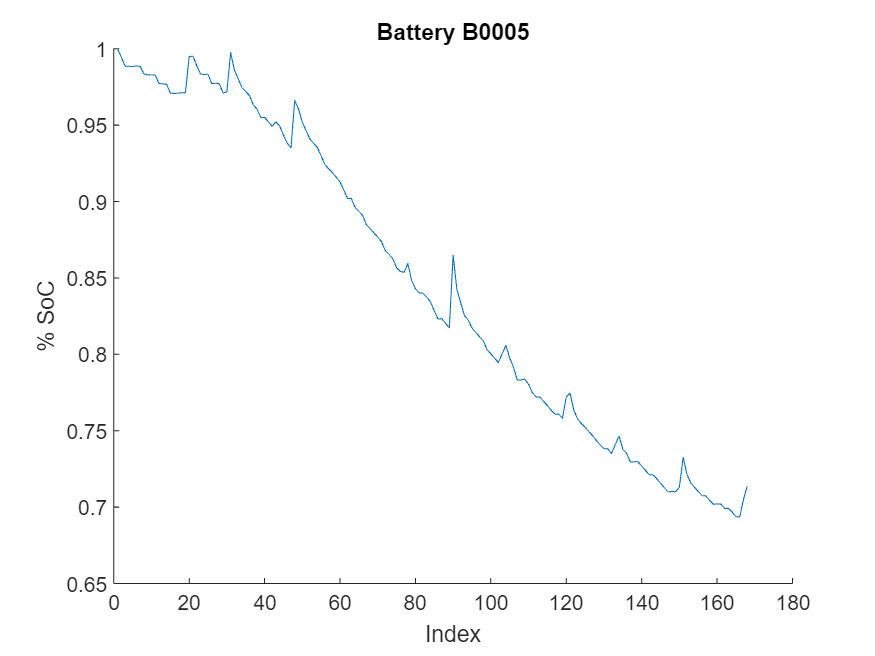


close all;

%%%% Load datasets %%%
battery_name = 'B0005';
data_path = append(pwd, '/', battery_name, '.mat');
dataset = load(data_path);
battery = dataset.B0005.cycle;
battery = struct2cell(battery);

%data = battery(4, 6)
%plot(data{1}.Time, data{1}.Voltage_load)
%hist(data{1}.Voltage_load)
%hist(data{1}.Voltage_load)

combined_cell = {};
discharge_count = 0;
for i = 1 : length(battery) 
    if ismember(battery(1,  i), {'discharge'}) == 1
        data = battery(4,  i);

        measured_v{discharge_count+1} = mean(normalize(data{1}.Voltage_measured, 'range'));

        measured_c{discharge_count+1} = mean(normalize(data{1}.Current_measured, 'range'));

        load_v{discharge_count+1} = mean(normalize(data{1}.Voltage_load, 'range'));

        load_c{discharge_count+1} = mean(normalize(data{1}.Current_load, 'range'));

        temperature{discharge_count+1} = mean(normalize(data{1}.Temperature_measured, 'range'));

        time{discharge_count+1} = mean(normalize(data{1}.Time, 'range'));
        
        capacity{discharge_count+1} = data{1}.Capacity;

        combined_cell = [combined_cell; {measured_v{discharge_count+1} measured_c{discharge_count+1} ...
            load_v{discharge_count+1} load_c{discharge_count+1} temperature{discharge_count+1} ...
            time{discharge_count+1} capacity{discharge_count+1} } ];
        discharge_count = discharge_count + 1;
    end
end 

%% Converted cell arrays into Table format, Prepered the data for cross validation %%

headers = ["Measured Voltage" "Measured Current" "Load Voltage" "Load Current" "Temperature" "time" "Capacity(State of Charge)"];
T = cell2table(combined_cell, "VariableNames",headers);
cv = cvpartition(size(T,1),'HoldOut',.3); % 70 persent of data set is now training data

%%% Export trating and testing data to csv file for implementations such as Neural Network %%%
Data_train = T(cv.training, :);
Data_test = T(cv.test, :);

writetable(Data_train,'train.csv');
writetable(Data_test,'test.csv');

train_features = [Data_train.("Measured Voltage") Data_train.("Measured Current") Data_train.("Load Voltage") Data_train.("Load Current") Data_train.("Temperature") Data_train.("time")];
train_labels = Data_train.("Capacity(State of Charge)");

test_features = [Data_test.("Measured Voltage") Data_test.("Measured Current") Data_test.("Load Voltage") Data_test.("Load Current") Data_test.("Temperature") Data_test.("time")];
test_labels = Data_test.("Capacity(State of Charge)");

%% Todo : We can try other sampling methods(Gibb's) to extract some meaningful values from cell arrays %%


%% Histogram approach for picking the most frequently appeared value in cell array %%

% h = histogram(load_c{9});
% % Retrieve some properties from the histogram
% V = h.Values
% E = h.BinEdges
% L = zeros(1, length(V))
% [x, y] = max(V)
% L (1, y) = 1
% L = logical(L)
% % Find the centers of the bins that identified as peaks
% left = E(L)
% right = E([false L])
% center = (left + right)/2 % the whole cell array might be replaced by this value ? 
% % Plot markers on those bins
% hold on
% plot(center, V(L), 'o')

%% Overall SoC persentage %%

charge_per = normalize([capacity{:}], 'norm', Inf);
figure;
hold on;
xlabel("Index");
ylabel("% SoC");
plot(1:length([capacity{:}]), charge_per); 
title(append('Battery ',battery_name));